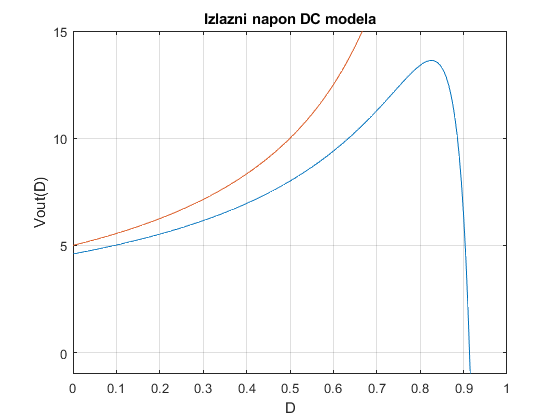

close all
clear
L=10e-6;
C=1000e-6;
rl=0.1;
rc=0.1;
A1=[-rl/L, 0; 0, 0];
B1=[1/L, 0;0, -1/C];
C1=[0, 1;1, 0];
D1=[0, -rc;0, 0];

A2=[-(rl+rc)/L,    -1/L; 1/C,   0];
B2=[1/L,  rc/L; 0, -1/C];
C2=[rc,  1; 1, 0];
D2=[0, -rc;0, 0];

%DC operating point
Vin=5;
Iout=4;
%Po D0
D0=0:0.005:0.999;
U0=[Vin;Iout];
Vout=zeros(1,length(D0));
for i=1:length(D0)
    %Averaged matrix
    A=A1*D0(i)+A2*(1-D0(i));
    B=B1*D0(i)+B2*(1-D0(i));
    C=C1*D0(i)+C2*(1-D0(i));
    D=D1*D0(i)+D2*(1-D0(i));

    %DC model
    X0=-inv(A)*B*U0;
    Y0=(D-C/A*B)*U0;
    Vout(i)=Y0(1,1);
end
plot(D0,Vout)
hold on
plot(D0,1./(1-D0)*5)
grid on
ylim([-1 15])
title('Izlazni napon DC modela')
xlabel('D')
ylabel('Vout(D)')

Dnom=D0(find(Vout>=10,1));
Vout(find(Vout>=10,1))

ans = 10.0003

A=A1*Dnom+A2*(1-Dnom)

A = 	1.0e+04 *

   -1.3650   -3.6500
    0.0365         0


B=B1*Dnom+B2*(1-Dnom)

B = 	1.0e+05 *

    1.0000    0.0365
         0   -0.0100


C=C1*Dnom+C2*(1-Dnom)

C =     0.0365    1.0000
    1.0000         0


D=D1*Dnom+D2*(1-Dnom)

D =          0   -0.1000
         0         0


X0=-inv(A)*B*U0

X0 =    10.9589
   10.0003


%Remaind
E=(A1-A2)*X0+(B1-B2)*U0;
F=(C1-C2)*X0+(D1-D2)*U0;
%Expand
B=[B E];
D=[D F];

%Linearizovano dinamicki model

Boost=ss(A,B,C,D);
Hs=tf(Boost)

Hs =
 
  From input 1 to output...
           3650 s + 3.65e07
   1:  ------------------------
       s^2 + 13650 s + 1.332e07
 
                1e05 s
   2:  ------------------------
       s^2 + 13650 s + 1.332e07
 
  From input 2 to output...
       -0.1 s^2 - 2232 s - 1.232e07
   1:  ----------------------------
         s^2 + 13650 s + 1.332e07
 
           3650 s + 3.65e07
   2:  ------------------------
       s^2 + 13650 s + 1.332e07
 
  From input 3 to output...
       -1.096 s^2 + 1.312e04 s + 2.408e08
   1:  ----------------------------------
            s^2 + 13650 s + 1.332e07
 
           1.07e06 s + 4e08
   2:  ------------------------
       s^2 + 13650 s + 1.332e07
 
Continuous-time transfer function.



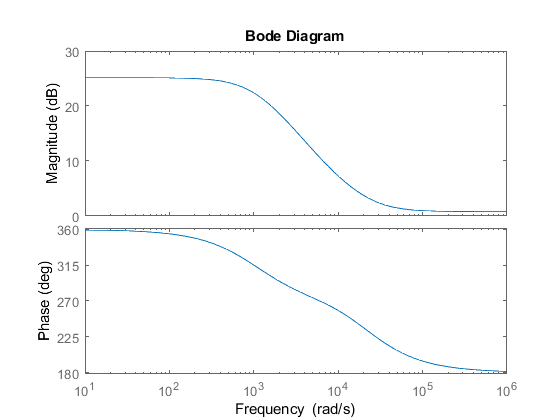

bode(Hs(1,3));

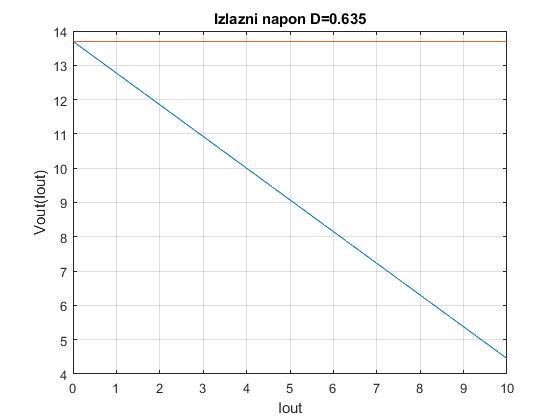

%Po Iout
Vin=5;
Iout=0:0.1:10;

Vout=zeros(1,length(Iout));
% Vout2=zeros(1,length(Iout));
for i=1:length(Iout)
    U0=[Vin;Iout(i)];
    %Averaged matrix
    A=A1*Dnom+A2*(1-Dnom);
    B=B1*Dnom+B2*(1-Dnom);
    C=C1*Dnom+C2*(1-Dnom);
    D=D1*Dnom+D2*(1-Dnom);

    %DC model
    X0=-inv(A)*B*U0;
    Y0=(D-C/A*B)*U0;
    Vout(i)=X0(2,1);
%     Vout2(i)=Y0(1,1);
end
figure()
plot(Iout,Vout)
hold on
plot([0 10],[5/(1-Dnom) 5/(1-Dnom)])
grid on
% ylim([-1 15])
title('Izlazni napon D=0.635')
xlabel('Iout')
ylabel('Vout(Iout)')

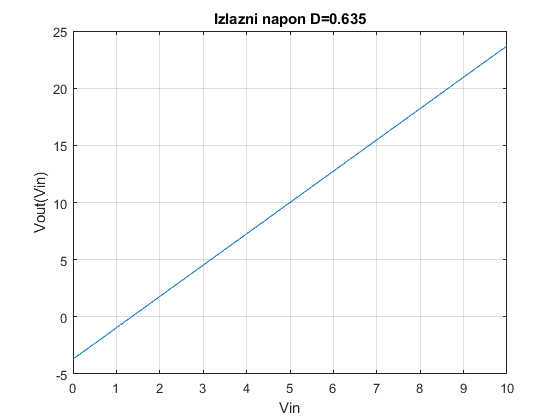

%Po Vin
Vin=0:0.1:10;
Iout=4;

Vout=zeros(1,length(Vin));
Vout2=zeros(1,length(Vin));
for i=1:length(Vin)
    U0=[Vin(i);Iout];
    %Averaged matrix
    A=A1*Dnom+A2*(1-Dnom);
    B=B1*Dnom+B2*(1-Dnom);
    C=C1*Dnom+C2*(1-Dnom);
    D=D1*Dnom+D2*(1-Dnom);

    %DC model
    X0=-inv(A)*B*U0;
    Y0=(D-C/A*B)*U0;
    Vout(i)=X0(2,1);
%     Vout2(i)=Y0(1,1);
end
figure()
plot(Vin,Vout)
grid on
% ylim([-1 15])
title('Izlazni napon D=0.635')
xlabel('Vin')
ylabel('Vout(Vin)')

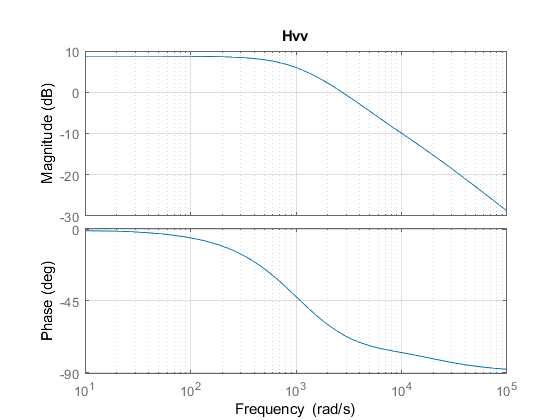

Hvv=Hs(1,1);
bode(Hvv)
grid on
title('Hvv')

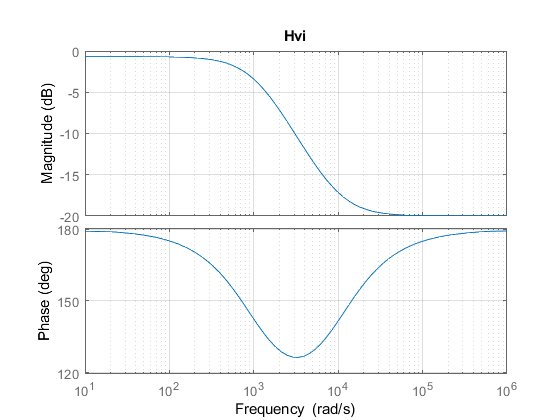

Hvi=Hs(1,2);
bode(Hvi)
grid on
title('Hvi')

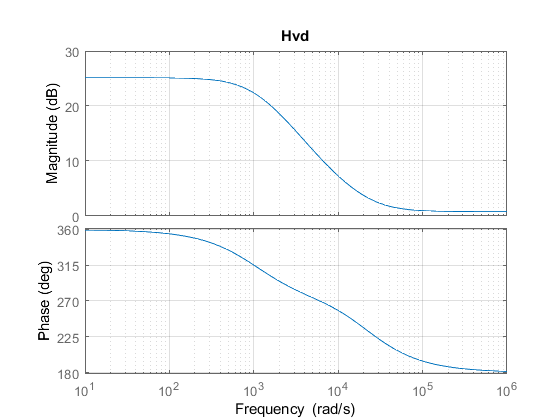

Hvd=Hs(1,3);
bode(Hvd)
grid on
title('Hvd')

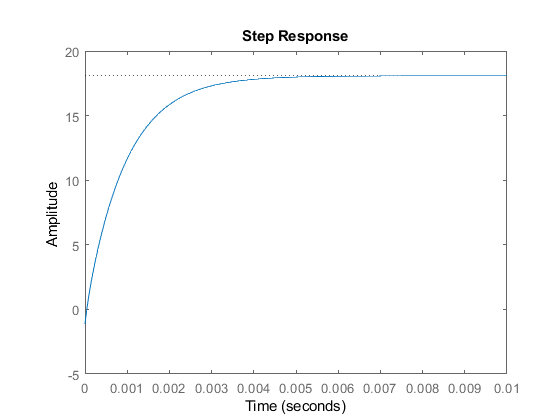


step(Hvd)

Hiv=Hs(2,1);
Hii=Hs(2,2);
Hid=Hs(2,3);
wc=0e4:5e3:3e4;
fc=wc./2/pi;

h = freqs(Hvd.Numerator{1},Hvd.Denominator{1},wc)

h =   18.0763 + 0.0000i   0.2808 - 3.9780i  -0.4765 - 2.2645i  -0.7248 - 1.6311i  -0.8524 - 1.2805i  -0.9260 - 1.0530i  -0.9716 - 0.8928i


mag = abs(h)

mag =    18.0763    3.9879    2.3141    1.7849    1.5383    1.4022    1.3195


phase = angle(h);
phasedeg = phase*180/pi;
180+phasedeg;

ans =   180.0000   94.0375   78.1159   66.0397   56.3515   48.6709   42.5770


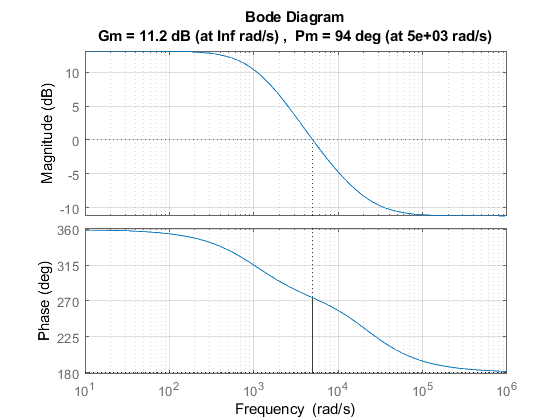

Hvd1=1/mag(2)*Hvd;
margin(Hvd1)
grid on

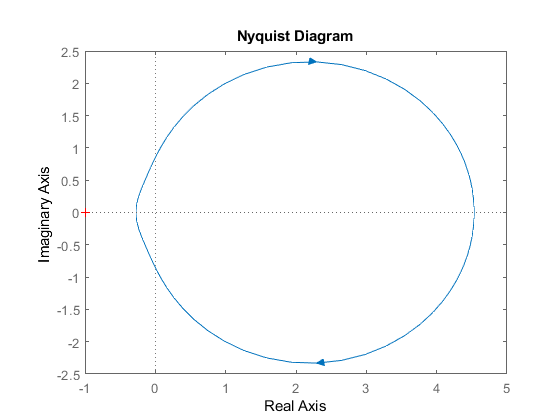

nyquist(Hvd1)

pmz=65

pmz = 65

pc=pmz-(180+phasedeg(2:3));
pc=deg2rad(pc);
p=sqrt((1+sin(pc))./(1-sin(pc)));
wc=wc(2);
p=p(1);
mag=1/mag(2);

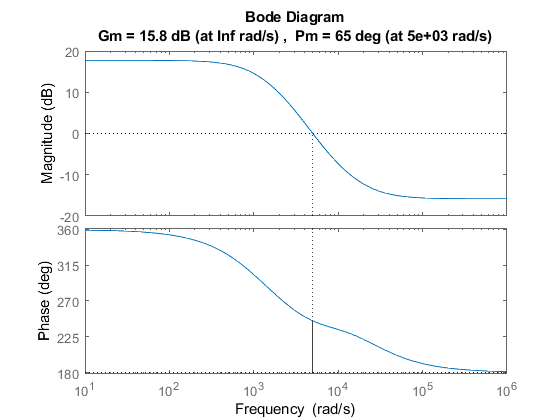

wz=wc/p;
wp=wc*p;
Glead=tf([p wc],[1 wc*p]);
Hvdlead=Glead*Hvd1;
margin(Hvdlead)

wl=wc/10;
Glag=tf([1 wl],[1 0])

Glag =
 
  s + 500
  -------
     s
 
Continuous-time transfer function.



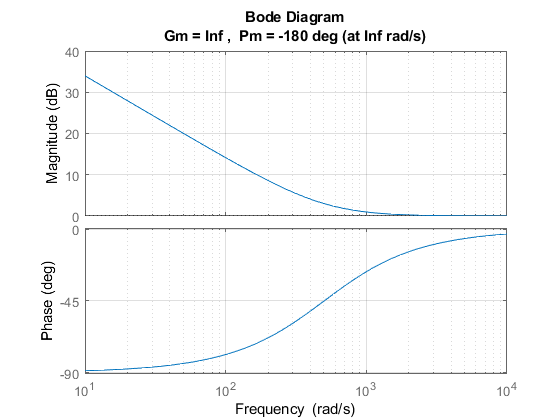

margin(Glag)
grid on

wclag=0e4:5e3:1e5;
h = freqs(Glag.Numerator{1},Glag.Denominator{1},wclag);
magl = abs(h);
Glag=1/magl(2)*Glag;
% margin(Glag*Hvdlead)
% grid on

Gcomp=Glag*Glead*mag;
W=tf(minreal(ss(Gcomp*Hvd)))

W =
 
  -0.1609 s^4 + 479.7 s^3 + 5.202e07 s^2 + 3.263e11 s + 1.502e14
  --------------------------------------------------------------
          s^4 + 1.659e04 s^3 + 5.349e07 s^2 + 3.921e10 s
 
Continuous-time transfer function.



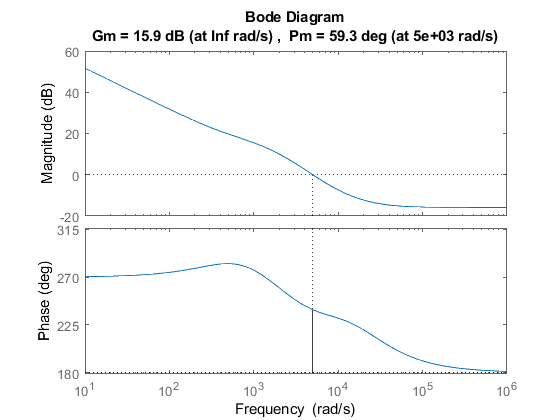

margin(Gcomp*Hvd)

Sprega=minreal(zpk(feedback(W,1)))

Sprega =
 
  -0.19182 (s-2.198e04) (s+1e04) (s+8495) (s+500)
  -----------------------------------------------
   (s+1.327e04) (s+470) (s^2 + 6610s + 2.871e07)
 
Continuous-time zero/pole/gain model.



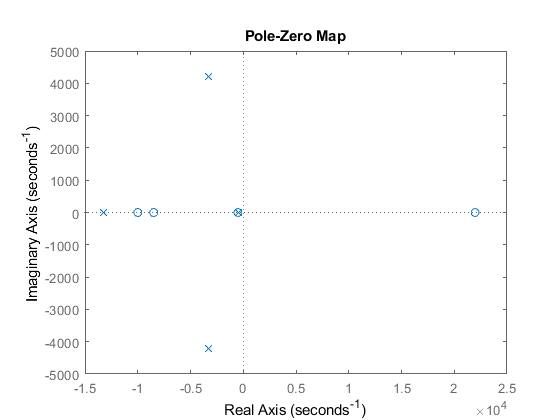

pzmap(Sprega)

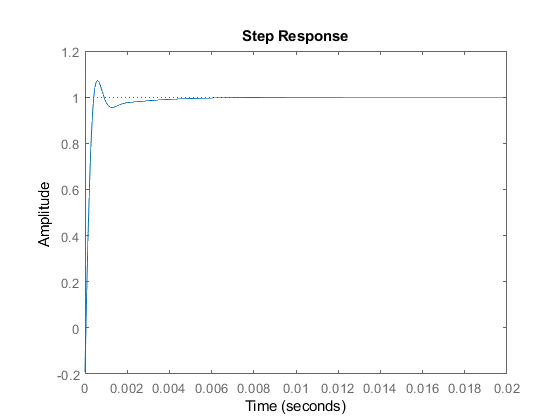

step(Sprega,0.02)

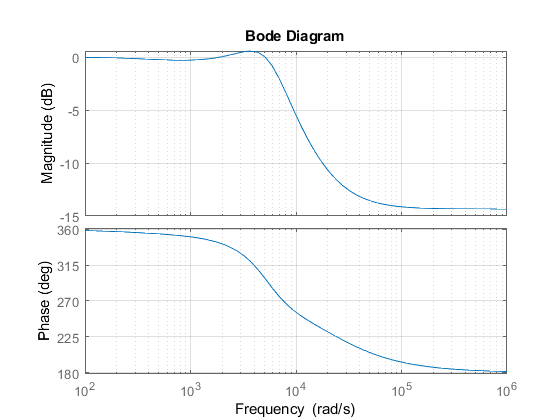


bode(Sprega)
grid on

Hvc=minreal(zpk(Hvd/Hid))

Hvc =
 
  -1.0246e-06 (s-2.197e04) (s+1e04)
  ---------------------------------
               (s+374)
 
Continuous-time zero/pole/gain model.



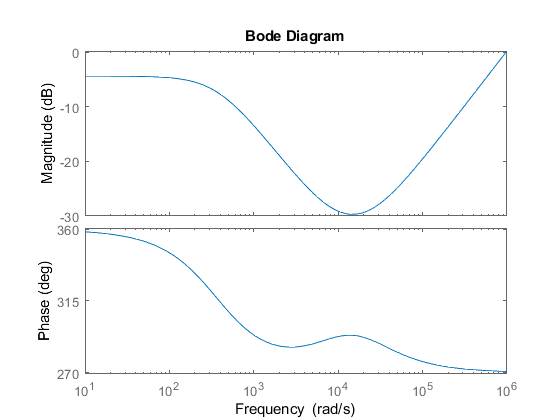

bode(Hvc)

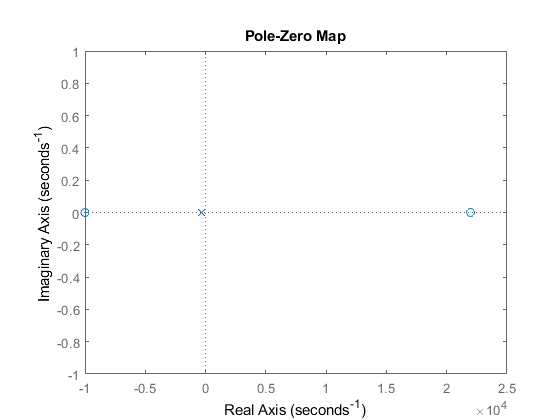

pzmap(Hvc)

Stab=zpk(tf(1,[1/1e4 1]));
Obj=minreal(Hvc*Stab)

Obj =
 
  -0.010246 (s-2.197e04)
  ----------------------
         (s+374)
 
Continuous-time zero/pole/gain model.



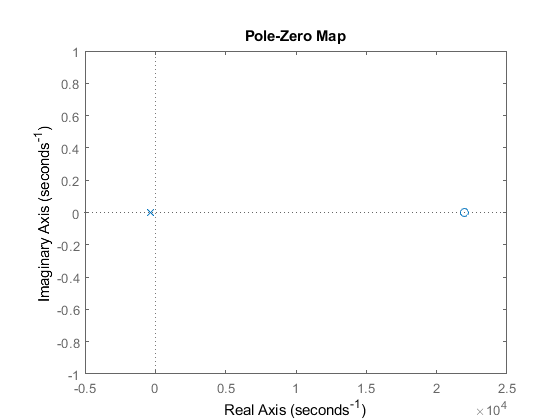

pzmap(Obj)

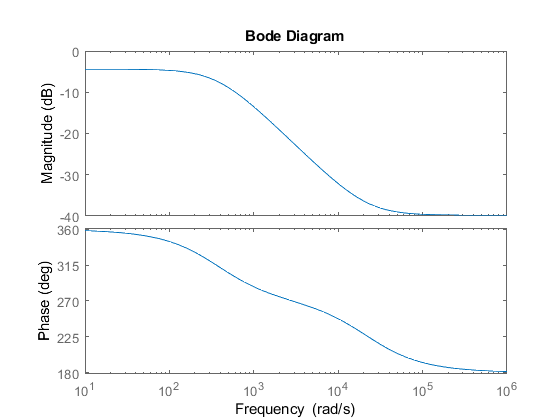

bode(Obj)

hcmc = freqresp(Obj,5e3) 

hcmc = -0.0068 - 0.0455i

magcmc = 1/abs(hcmc)

magcmc = 21.7147

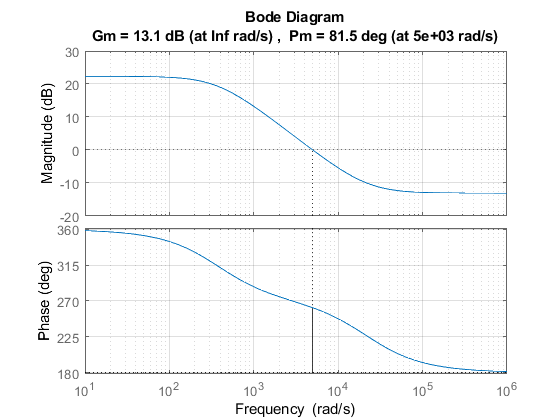

Objcmc=magcmc*Obj;
margin(Objcmc)
grid on


wl=wc/10;
Glagcmc=zpk(tf([1 wl],[1 0]))

Glagcmc =
 
  (s+500)
  -------
     s
 
Continuous-time zero/pole/gain model.



Gcmc=magcmc*Glagcmc

Gcmc =
 
  21.715 (s+500)
  --------------
        s
 
Continuous-time zero/pole/gain model.



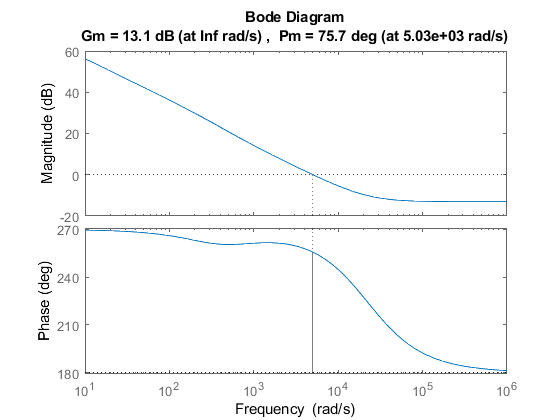

margin(Gcmc*Obj)

Wcmc=minreal(Gcmc*Obj)

Wcmc =
 
  -0.22248 (s+500) (s-2.197e04)
  -----------------------------
            s (s+374)
 
Continuous-time zero/pole/gain model.



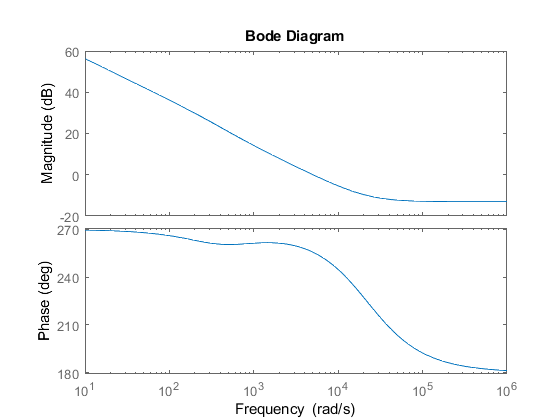

bode(Wcmc)

Spregacmc=feedback(Wcmc,1)

Spregacmc =
 
  -0.28614 (s-2.197e04) (s+500)
  -----------------------------
       (s+514.4) (s+6111)
 
Continuous-time zero/pole/gain model.



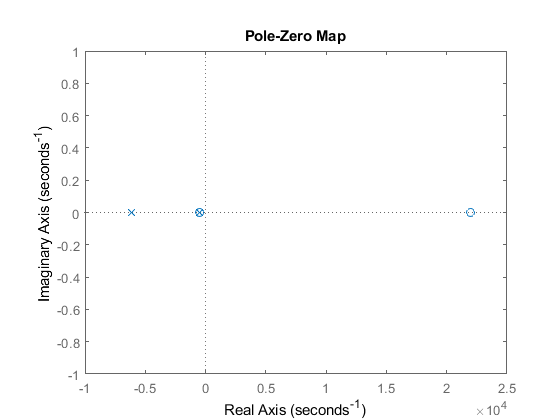

pzmap(Spregacmc)

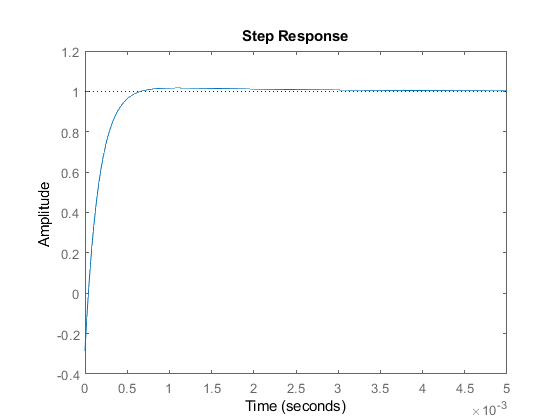

step(Spregacmc)

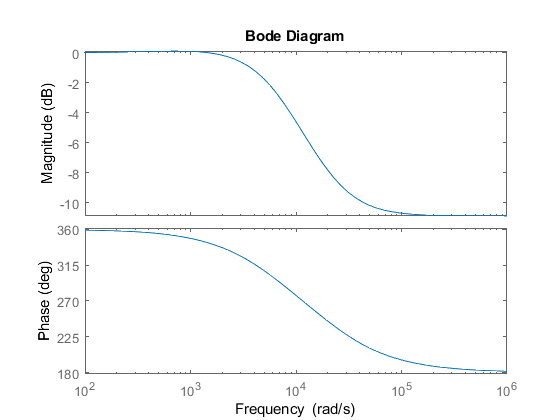

bode(Spregacmc)